# The Trapezoid Rule

***Author****: Dr. Matthew Leineweber, San Jose State University*

## Introduction

In calculus, you were introduced to the concept of integration. Specifically, the *definite integral* of a function $f(x)$ over the range $a \leq x \leq b$ is denoted:


$$I = \int_a^bf(x)dx$$


The integral $I$ can be represented graphically as shown in Figure 1.

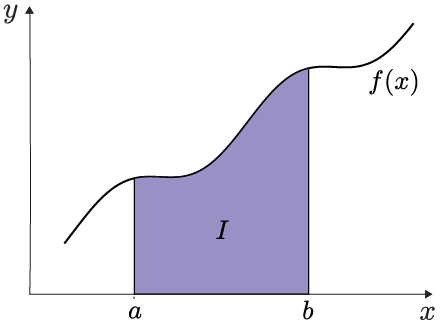

**Figure 1: **The definite integral of $f(x)$ over the range $a\leq x \leq b$ is equal to the area under the curve defined by $f(x)$ over that range.

While this integral can sometimes be computed analytically, so long as the anti-derivative $F(x)$ of $f(x)$ is known, there are often cases where the anti-derivative is either impossible or very difficult to obtain. In these situations, it becomes necessary to approximate the value of the definite integral using other means. By realizing that the value computed by the definite integral, $I$, simply represents the area under $f(x)$, we might see that we could estimate $I$ by separating the shaded region in Figure 1 into smaller sub-regions whose areas can be easily calculated, and then summing these areas. This technique is called *numerical quadrature* and uses interpolating polynomials to approximate $f_n(x)$ over each sub-region. Specifically, numerical quadrature equations state:


$$I = \int_a^b{f(x) dx} \approx \int_a^b{f_n(x) dx}$$


where $f_n(x)$ is an $n^{th}$-degree polynomial of the form:


$$f_n(x) = a_0 + a_1x + \dots + a_{n-1}x^{n-1}+a_nx^n$$


that approximates the function $f(x)$ over the region $a\leq x \leq b$. In the activity below, use the slider-bars to select the values for $a$ and $b$, as well as the degree of polynomial $n$ to visualize how the integral approximation is affected by each term.

#### Activity 1: Visualizing numerical quadrature

Use the sliders below to select the left bound of integration $a$, right bound of integration $b$, and the order of the polynomial to be used to represent $f(x)$ over the $[a,b]$ interval.

a =1;
b =6;
n =1;

PolyExample(a,b,n)

#### Question set 1

- Change the limits of integration so that you are evaluating the integral over the interval $[3,6]$. Explore the effect of changing $n$ on this interval. Which degree polynomial best approximates the function?

- Now change the interval to $[4,6]$. How much does changing $n$ affect the estimate of the integral?

- Finally, select the interval $[6,6.5]$. How does changing $n$ affect the estimate of the integral?

- Based on your observations in questions 1, 2, and 3, what effects do your choice of $a$, $b$, and $n$ have on the accuracy of your integral approximations?

## Trapezoid rule

In the previous activity, you probably saw that higher-degree polynomials provided the best approximation of $f(x)$, and that the closer $a$ and $b$ were to each other, the better the polynomial $f_n(x)$ approximated the function $f(x)$. However, these higher-order polynomials can be difficult to integrate and choosing a different polynomial for each $f(x)$ can be time-consuming and impractical.

In the previous activity, you probably saw that first-degree polynomials (i.e. lines) provided a good approximation of $f(x)$ when  $[a,b]$ was small. Indeed, for small intervals, any function $f(x)$ can be approximated with a first-order polynomial:


$$f_1(x) = a_0 + a_1x$$


where $a_0 = f(a)$ and $a_1 = \frac{f(b)-f(a)}{b-a}$. Substituting these terms into our numerical quadrature approximation produces:


$$I \approx \int_a^b{f_1(x) dx} = \int_a^b{\left[f(a) + \frac{f(b)-f(a)}{b-a} (x-a) \right]} dx$$


Evaluating the integral produces:


$$I\approx \left(b-a\right)\frac{f(a)+f(b)}{2}$$


This approximation is called the *trapezoid rule*. But what if we want to use this approximation for larger intervals $[a,b]$? We already saw that this linear approximation is not always a good fit. However, what if we broke the interval into smaller sub-intervals? Recall that an integral can be calculated piecewise:


$$I = \int_a^b{f(x) dx} = \int_a^{x_1}{f(x) dx} + \int_{x_1}^{x_2}{f(x) dx} + \dots + \int_{x_{n-1}}^b{f(x) dx}$$


where $x_1, x_2, \dots x_{n-1}$ lie on the $[a,b]$ interval. Using this sub-interval approximation, we can rewrite the integral as


$$I = I_0 + I_1 + I_2 + \dots + I_{n-1}$$


and define:


$$I_i = \int_{x_i}^{x_{i+1}}{f(x) dx}$$


So, if we let $f(x) \approx f_1(x) = f(x_i) + \frac{f(x_{i+1})-f(x_i)}{x_{i+1}-x_i}(x-x_0)$, we see that


$$I_i \approx \left(x_{i+1}-x_i\right)\frac{f(x_i)+f(x_{i+1})}{2}$$


So, our integral becomes:


$$I \approx \left(x_{1}-x_0\right)\frac{f(x_0)+f(x_{1})}{2} + \left(x_{2}-x_1\right)\frac{f(x_1)+f(x_{2})}{2} + \dots + \left(x_{n}-x_{n-1}\right)\frac{f(x_{n-1})+f(x_{n})}{2}$$


If we choose $[x_0,x_1, x_2, \dots, x_{n}]$ to be $n+1$ evenly spaced points on the interval $[a,b]$, then $\Delta x = x_{i+1}-x_i = \frac{b-a}{n}$ with $x_0 = a$ and $x_n=b$. Substituting these values into the previous equation produces:


$$\begin{array}{rcl} 
I & \approx & \left(a + \Delta x-a\right)\frac{f(a)+f(x_{1})}{2} + \left(a+2\Delta x-(a + \Delta x)\right)\frac{f(x_1)+f(x_{2})}{2} + \dots + \left(b-(a+(n-1)\Delta x)\right)\frac{f(x_{n-1})+f(b)}{2} 
\\ 
& = & \Delta x\frac{f(a)+f(x_1)}{2} + \Delta x\frac{f(x_1)+f(x_2)}{2} + \dots + \Delta x \frac{f(x_{n-1})+f(b)}{2} 
\\ 
& = & \frac{\Delta x}{2}\left[f(a) + 2\sum\limits_{i=1}^{n-1}{f(x_i)} + f(b)\right]
 \end{array}$$


Substituting for $\Delta x$ produces the *multiple trapezoid rule*:


$$I \approx \frac{b-a}{2n}\left[f(a) + 2\sum\limits_{i=1}^{n-1}{f(x_i)} + f(b)\right] \end{array}$$


This equation means that the area under any curve can be approximated by a summation of a finite number of $n$ trapezoids over the interval $[a,b]$. In the next activity, we'll explore how changing the number of trapezoids (i.e. changing $n$) affects our integral approximation.

#### Activity 2: How does the number of sub-intervals affect our estimate

In this activity, we will use the multiple trapezoids rule to integrate the function:


$$f(x) = xe^{-x^{-0.08}} + 0.2$$


Over the range $0\leq x \leq 8$. You'll be able to select the number of trapezoids being used for the approximation. Before proceeding with this activity, take a few minutes to try and integrate this function analytically. You will find that it does not have an explicit anti-derivative solution. Therefore, we must numerically integrate to find a solution.

To start this activity, select a value for $n$ using the slider below.

n =1;
nExample(n)

#### Question set 2

- How does changing the number of intervals affect the numerical approximation of the integral?

- Can you think of any downsides of using a large $n$?

### Developing an algorithm for the multiple trapezoid rule with equally spaced data

Looking at our definition of the multiple trapezoids rule:


$$I = \frac{b-a}{2n}\left[f(a) + 2\sum\limits_{i=1}^{n-1}{f(x_i)} + f(b)\right] \end{array}$$


we can see that it has four major components:

- The function to be integrated: $f(x)$

- The limits of the range over which the function $f(x)$ is to be integrated: $a$ and $b$

- The number of sub-intervals $n$

- A summation of $f(x_i)$ for each point $x_i$ on the range $a \leq x \leq b$.

Therefore, if we were to write an algorithm to perform trapezoidal rule numerical integration, we would want to perform the following steps:

- Specify the function $f(x)$ to be integrated, the limits of integration $a$ and $b$, and the number of intervals $n$

- Use $a$ and $b$ to define the interval width, $\Delta x = \frac{b-a}{n}$

- Define the $x_i$ points: $x_i = a + i\Delta x$, $i = 1,2,\dots,n-1$

- Evaluate $f(x_i)$ at each $x_i$ point, and then sum all the values

- Use the trapezoid rule formula to approximate the integral

#### Activity 3: Performing an Integral with the multiple trapezoids rule

Now that we have a set of steps outlining our algorithm, we can write a script to perform the trapezoid rule integration to solve the following integral:


$$\int_5^{10}{2x^{0.5}dx}$$


using five intervals ($n=5$). We can write our code following each of the five steps:

**Step 1:** Specify the function $f(x)$ to be integrated as an [anonymous function](https://www.mathworks.com/help/matlab/matlab_prog/anonymous-functions.html), the limits of integration $a$ and $b$, and the number of intervals $n$

% function to be integrated, f(x)

% limits of integration

% define the number of intervals


**Step 2: **Use $a$ and $b$ to define the interval width: $\Delta x = \frac{b-a}{n}$

**Step 3: **Define the $x_i$ points: $x_i = a + i\Delta x$, $i = 1,2,\dots,n-1$

**Step 4: **Evaluate $f(x_i)$ at each $x_i$

**Step 5: **Use the trapezoid rule formula to approximate the integral

To check the accuracy of our trapezoid rule approximation, we can compare our answer against the analytical solution:


$$\begin{array}{rcl} F & = & \int_5^{10}{2x^{0.5}dx} \\ & = & \left. \frac{4}{3}x^{1.5}\right|_5^{10} \\ & = & \frac{4}{3}\left(10^{1.5} - 5^{1.5}\right) \\ & = & 27.27 \end{array}$$


We can see that our approximation is very similar to our analytical solution. Even with relatively few trapezoids, we get a decent approximation of our function ($0.04\%$ error). 

**Step 6: **Use the helper function `PlotTrapezoidRule` to visualize the result. The function has the syntax:

where `a` and `b` are the limits of integration, `dx` is the interval width, `fx` is the function handle, and `n` is the number of intervals.

### Integrating from tabulated data

So far, we have always had a mathematical expression for $f(x)$ when performing our integrals. However, it is often the case that the expression $f(x)$ is unknown, and all that is given is a set of tabulated values for $x_i$ and $f(x_i)$, as shown below:


$$\hline  \begin{array}{|r|r|r|r|r|} \hline \mathbf{x_i} & x_0 & x_1 & \dots & x_{n-1}\  \\ \hline \ \mathbf{f(x_i)} & f(x_0) & f(x_1) & \dots & f(x_{n-1}) \ \\ \hline \end{array}$$


In this case, there is no guarantee that the $x_i$ values will be evenly spaced. In other words, The difference between successive $x_i$:


$$\Delta x_i = x_{i+1} - x_i$$


may be different for each value of $i$. This means that our definition of $\Delta x = \frac{b-a}{n}$ is no longer valid. Revisiting our equations from the first section of this script shows us that we can return to our earlier approximation:


$$\begin{array}{rcl} I & \approx & I_0 + I_1 + \dots + I_{n-1} \\  & = &\left(x_{1}-x_0\right)\frac{f(x_0)+f(x_{1})}{2} + \left(x_{2}-x_1\right)\frac{f(x_1)+f(x_{2})}{2} + \dots + \left(x_{n}-x_{n-1}\right)\frac{f(x_{n-1})+f(x_{n})}{2} \end{array}$$


We can see that each term $I_i$ can be written as:


$$I_i = \frac{\Delta x_i}{2}\left(f(x_i) + f(x_{i+1})\right); \quad i = 0,1,2,\dots,n-1$$


Therefore, for unevenly spaced points, our multiple trapezoids rule can be written as:


$$I\approx \frac{1}{2}\sum\limits_{i=0}^{n-1}{\left[\Delta x_i\left(y_i + y_{i+1}\right)\right]$$


Here we define $y_i = f(x_i)$ and $y_{i+1} = f(x_{i+1})$ for ease of notation. Note that this equation requires that $x_{i+1}\geq x_i$ for all values of $i$. 

Again, looking at the equation for $I$, we can see that there are four components to this equation:

- Calculating the step size by subtracting successive values of $x_i$: $\Delta x_i = x_{i+1} - x_i$

- Adding $y_i$ to the next value $y_{i+1}$

- Summing the product of step 1 and step 2 for all values of $i$

- Dividing the result by two.

Therefore, we can write pseudocode to describe this calculation process:

#### Activity 4: Writing an algorithm for the multiple trapezoids rule with tabulated data

In this activity, we will work to complete an algorithm to approximate the area of the tabulated data provided below:

T = TabulatedData
% Plot the data
plot(T.x,T.y,"o",SeriesIndex="none")
xlabel("x")
ylabel("y")
grid on
hold on
set(gca,"XAxisLocation","origin","XTick",0:0.25:3)

We can see that the data table contains 26 pairs of $(x,y)$ data corresponding to $(x_i, f(x_i))$ for some unknown function $f(x)$. We can start the integration process by identifying our $x$ and $y$ data:

x = T.x;
y = T.y;

Now that the data has been selected, we are ready to start the integration process. Looking at the data table, we see that there are 26 data points that need to be accounted for, therefore, $n=26$, and our $i$ counter should go from $1$ to $n-1 = 25$. Use the template below to complete the algorithm for the multiple trapezoids rule using our pseudocode provided above:

% Perform the Integration
I = 0;              % Initialize a variable for our integral
n = numel(x);       % Number of points in the dataset
for i = 1:(n-1)
    % Fill in the loop to complete the calculation for the integral, I


    area(x(i:i+1),y(i:i+1),FaceAlpha=0.15,SeriesIndex=1)
end
hold off
fprintf("I = %2.3f",I)

#### Activity 5: Challenge! Vectorizing the trapezoid rule

In many cases, working with vectors and vector operations yields more compact and efficient code than for loops. Therefore, a more efficient way to perform our trapezoid rule calculations would be to avoid using loops altogether. In our code for Activity 3, we saw that the loop performed three functions:

- Calculating the step size by subtracting successive values of $x_i$: $\Delta x_i = x_{i+1} - x_i$

- Adding $y_i$ to the next value $y_{i+1}$

- Summing the product of step 1 and step 2 for all values of $i$

It is possible to perform all three of these functions using other MATLAB commands.

The [`diff`](https://www.mathworks.com/help/matlab/ref/diff.html) function calculates the forward finite difference of the vector $n$-element vector $x$, so that $dx(i) = x(i+1) - x(i)$ for $i = 1,2,\dots,n-1$. For example:

dx = diff(x)

You can use [array indexing](https://www.mathworks.com/help/matlab/math/array-indexing.html) to select a subset of elements from an array. For example:

ysub = y(1:end-1)

Finally, recall that the [`sum`](https://www.mathworks.com/help/matlab/ref/sum.html) function can add up all the elements in a vector.

As a challenge problem, in the space provided below, use these three functions to write a set of commands that performs the trapezoid rule on a set of $(x,y)$ data in no more than two lines of code.

% Enter your code in the space below



## Function Definitions

function PolyExample(a,b,n)
% Define function to be integrated
x = 0:0.01:12;
fy = @(x) sin(pi/12*x) + cos(pi/4*x) + 0.5;

% Plot
figure
plot(x,fy(x),LineWidth=1,SeriesIndex="none")
xlabel("$x$",Interpreter="latex")
ylabel("$f(x)$",Interpreter="latex")
title("Integrating with Polynomials")

% Fit polynomial
xn = a:0.1:b;
if n == 1
    xn = [a b];
    yfit = fy([a b]);
else
    p = polyfit(xn,fy(xn),n);
    yfit = polyval(p,xn);
end

% integrate
F = trapz(xn,yfit);

% Plot area
hold on
plot(xn,yfit,"--",LineWidth=1,SeriesIndex=1)
area(xn,yfit,FaceAlpha=0.15,SeriesIndex=1,EdgeColor="none")
hold off
text(xn(1),-0.05,"a")
text(xn(end),-0.05,"b")
title("Activity 1")

legend("$f(x)$","$f_n(x)$","$I$",Location="Northwest",Interpreter="latex")

text(2,1.5,"$I \approx$ " + num2str(F,5),Interpreter="latex")
end

function nExample(n)
%Code for Activity 2
% Define x vector:
x = linspace(0,8,n+1);

% Define y-vector using f(x) defined in Activity 2
fx = @ (x) x.*exp(-x.^0.8)+0.2;
y = fx(x);

% Perform trapezoidal integration
q = trapz(x,y);

% Plot Area Under the Curve
plot(linspace(0,8,200),fx(linspace(0,8,200)),LineWidth=1,SeriesIndex="none")
hold on
xlabel("$x$",Interpreter="latex")
ylabel("$f(x)$",Interpreter="latex")
set(gca,"FontSize",11)
title("Activity 2")
for i = 1:numel(x)-1
    area(x(i:i+1),y(i:i+1),SeriesIndex=1,FaceAlpha=0.15)
end
hold off
s1 = sprintf("$I$, n = %d",n);
legend("$f(x)$",s1,FontSize=11,Interpreter="latex")


% Display Integral
text(5,0.4,"$I\approx$ " + num2str(q,4),Interpreter="Latex",FontSize=11)
end

function T = TabulatedData
% Some unknown function data
Col1 = [0:0.25:1, 1.1:0.05:1.2, 1.2:.1:2.6 2.6 2.8 3]';
Col2 = [2.0000 2.4392 2.0000 0.7071 -1.0000 -1.6473 -1.9403 -2.2058 -2.2058 -2.6361 -2.9074 -3.0000 -2.9074,...
    -2.6361 -2.2058 -1.6473 -1.0000 -0.3090 0.3787 1.0181 1.5691 2.0000 2.2893 2.2893 2.4149 2.0000]';

T = table(Col1,Col2,VariableNames=["x";"y"]);
end

function PlotTrapezoidRule(a,b,dx,fx,n)
% define a full range of x values between a and b
x = linspace(a,b,100);
xi = a:dx:b;
y = fx(x);

% Plot
figure
plot(x,y,LineWidth=1,SeriesIndex="none")
hold on
xlabel("x")
ylabel("f(x)")
set(gca,"FontSize",11)
for ii = 1:numel(xi)-1
    area(xi(ii:ii+1),fx(xi(ii:ii+1)),SeriesIndex=1,FaceAlpha=0.08*(1+(-1)^ii)+0.15)
end
hold off
s = sprintf("$F(x)$, n = %d",n);
legend("$f(x)$",s,FontSize=11,Interpreter="latex",Location="Northwest")
end